# **Procesamiento de Imagenes Digitales**

# **Taller 3**

## Filtro espacial de la media

Dentro de los filtros espaciales de suavizado, al filtro de la media se le atribuye cierta eficiencia a la hora de reducir el deterioro causado por ruido gaussiano en las imágenes. A continuación, se presenta una opción para utilizar este tipo de filtros en Matlab, alternativa la función` nlfilter:`

`k=ones(m,n)/m*n`

`Im=imfilter(I,k)`

en donde `I` es la imagen original,` Im` la imagen filtrada, y` k` el filtro de media definido con su respectivo tamaño `mn`.

La popular imagen cameraman ha sido afectada por ruido gaussiano, como se muestra en la figura a continuación: 

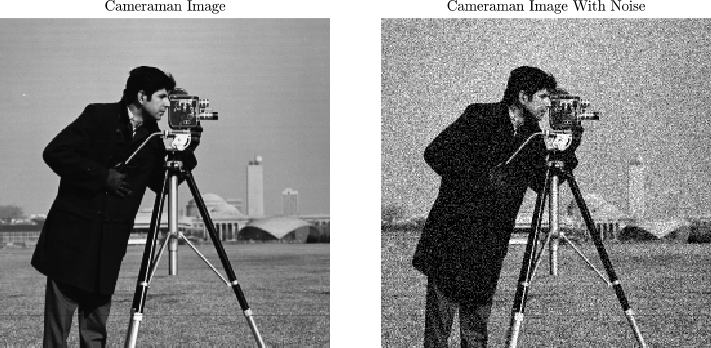

Procese la imagen cameramanNOISE.tif con filtros de media, de ventanas 3x3, 5x5, y 7x7. Visualice las 3 imágenes en un subplot horizontal, agregue como titulo el tamaño del filtro para cada imagen procesada, y termine con su conclusión. 

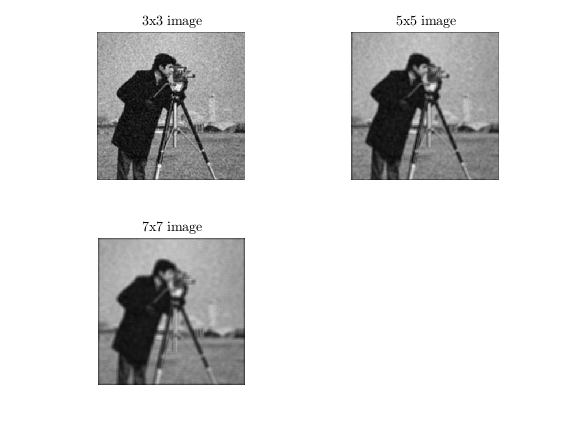

I = imread('cameramanNOISE.tif');
k1 = ones(3,3)/9;
k2 = ones(5,5)/25;
k3 = ones(7,7)/49;
I1 = imfilter(I,k1);
I2 = imfilter(I,k2);
I3 = imfilter(I,k3);
figure(1);
subplot(2,2,1);imshow(I1);colormap gray;title('3x3 image','Interpreter',"latex");
subplot(2,2,2);imshow(I2);colormap gray;title('5x5 image','Interpreter',"latex");
subplot(2,2,3);imshow(I3);colormap gray;title('7x7 image','Interpreter',"latex");

Tenemos que los filtros de suavisado ayuda a disminuir el ruido de la imagen, pero a su vez entre mas abarque le filtro o mas grande sea, mas difuminada será la imagen y disminuira la nitidez de la imagen, por lo que se debe de encontrar cual filtro es el adecuado para la imagen y termine en un termino medio entre estas 2 opciones y quede con un ruido minimo pero no con un difuminado tan borroso.

## Filtro espacial de la mediana

Por otro lado, al filtro espacial que se basa en el concepto estadístico de la mediana se le atribuye mejor desempeño a la hora de reducir el ruido “sal y pimienta” que deteriora una imagen. En Matlab, está disponible la función `medfilt2` para aplicarlo.

`Im = med2filt2(I,[m n])`

Cargue la imagen “camerameanSALTPAPPER.tif” y visualícela  y titulela "Cameraman Image Salt & Papper" para que observe el ruido que afecta la imagen. 

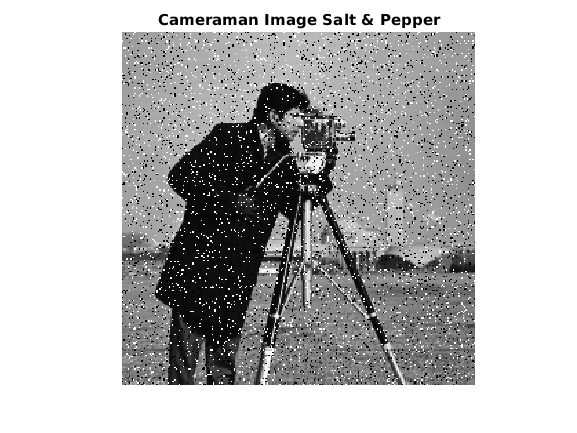

figure(2);
Isaltpapper = imread('cameramanSALTPAPPER.tif');
imshow(Isaltpapper);colormap gray;title('Cameraman Image Salt & Pepper');

Procese la imagen con un filtro de mediana de tamaño 3 x 3, y visualice el resultado. 

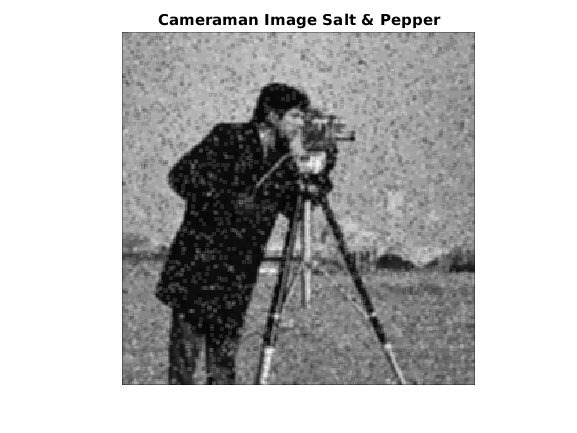

Isaltpapper = imread('cameramanSALTPAPPER.tif');
k1 = ones(3,3)/9;
Isaltpapper1 = imfilter(Isaltpapper,k1);
figure(3);
imshow(Isaltpapper1);colormap gray;title('Cameraman Image Salt & Pepper');

Incluya el argumento “symmetric” `Im = med2filt2(I,[m n],'symmetric') `con el mismo tamaño de filtro, visualice, compare con la imagen anterior y agregue su conclusión

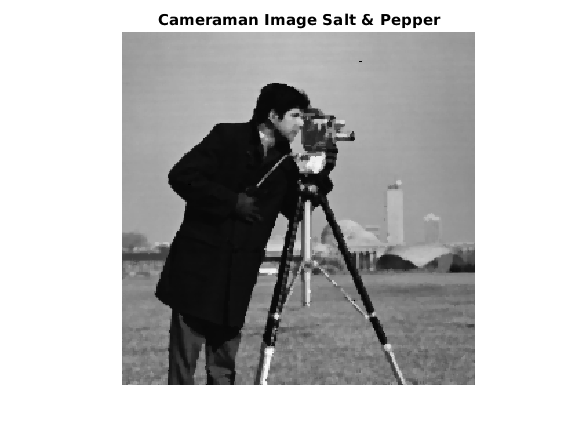

Isaltpapper = imread('cameramanSALTPAPPER.tif');
Isaltpapper2 = medfilt2(Isaltpapper,[3,3],'symmetric');
figure(4);
imshow(Isaltpapper2);colormap gray;title('Cameraman Image Salt & Pepper');

A diferencia de los filtros anteriores el filtro de la función medfilt2 junto con el parametro symmetric no difumina tanto los bordes si no que los realza, ademas de quitar el ruido de la imagen.

## Filtre la imagen 

Cargue la imagen “circuit.tif”, visualice la imagen para que observe el ruido y aplique el filtro, de tamaño 3x3, que usted estime conveniente para reducir la mayor cantidad de ruido. Visualice la imagen resultante y agregue su conclusión.

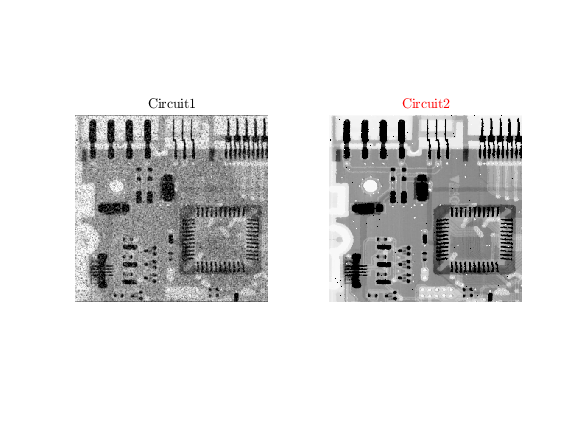

Icircuit = imread('circuit.tif');
k1 = ones(3,3)/9;
Icircuit1 = imfilter(Icircuit,k1);
Icircuit2 = medfilt2(Icircuit,[3,3],'symmetric');
figure(5);
subplot(1,2,1);imshow(Icircuit1);colormap gray;title('Circuit1','Interpreter',"latex");
subplot(1,2,2);imshow(Icircuit2);colormap gray;title('Circuit2','Interpreter',"latex",'color','r');

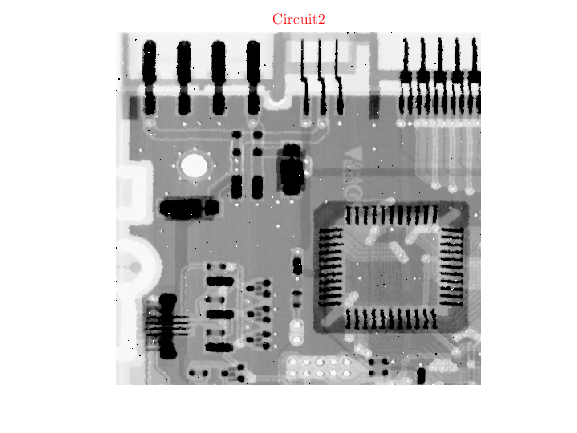

figure(6);
imshow(Icircuit2);colormap gray;title('Circuit2','Interpreter',"latex",'color','r');

Resulta mas conveniente el filtro de la función medfilt2 que da la imagen Circuit2, dado que la imagen resulta mas detallada y pierde casi todo su ruido, ademas resalta los bordes y no los difumina.